# Predicting Restaurant Success based on Location and Cuisine Type Using Machine Learning

## Project Idea

Running a successful restaurant is difficult. Restaurant owners must worry about supplying ingredients, hiring cooks and servers, and ensuring enough patrons come to eat their food. Especially with the pandemic, opening a restaurant is a very risky investment. One source has found that about 60% of restaurants close within the first year - and 80% close within the first 5 years. These statistics are scary for people aspiring to start a restaurant, as they will need to invest a significant amount of time and money that could go to waste. 

The biggest factor that goes into the success of a restaurant is location. Different types of cuisine will do better in different locations because of the demographics of an area. Furthermore, more lively areas tend to attract more business. Availability of parking, rent, visibility from main roads, etc. all also factor into the success of a restaurant.

In order to make the process of starting a restaurant easier for the owner, we plan to use machine learning to make a program that can predict the success of a restaurant based on its location. Our algorithm will also factor in what categories of food it will offer. Based on that, our program will return a score out of 5 rating the area for the restaurant’s personalized needs. This will be very useful for potential restaurant owners, as they will be able to get a good sense of what a good location might be before spending a lot of money.

We will use the yelp dataset, which contains information about 160,585 businesses. The datasheet aggregates various data points about each restaurant, and then its yelp ranking (out of 5, in 0.5 intervals). We will import this data into Matlab and clean it to only have the relevant data we need. From there, we will use the Statistics and Machine Learning Toolbox to create our algorithm.

## Article on Bias Summary

Data bias is a type of error in which certain parts of a dataset are overdensely weighted or represented than others in machine learning. A biased dataset will have a negative effect on machine learning models because it does not represent a model’s use case accurately when making decisions or informing decisions using these machine learning models. Unfortunately, they can lead to biased results, low accuracy of results, and analytical errors. Data bias exists in a different range of areas such as human reporting and selection bias and algorithmic bias. In this case, it is significant to be careful about the quality and formation of the data collected to avoid bias possibly. Six different biases that we need to be concerned about when applying machine learning algorithms are introduced. We have automation bias, which is a tendency of humans to favor results generated by automated systems instead of ignoring the information provided by the non-automated systems. Selection bias, involving surveys and researches, occurs when the selected data does not reflect the real world data distribution, so randomization is crucial when collecting data. Overgeneralization bias occurs when people review and assume the dataset as the same information they see in other datasets, ignoring how large the dataset is. Group attribution bias occurs when people tend to stereotype the whole population according to the actions of a small number of individuals within the population. Reporting bias happens when only a small fraction of the entire real-world data is used. Lastly, assumptions based on personal experiences force people to act on basis of prejudice and stereotypes. 

Kangralkar, Swapnil. “Types of Biases in Data.” *Medium*, Towards Data Science, 26 Aug. 2021, [https://towardsdatascience.com/types-of-biases-in-data-cafc4f2634fb](https://towardsdatascience.com/types-of-biases-in-data-cafc4f2634fb). 

## Importing the Data

First, we downloaded the yelp data set from [https://www.yelp.com/dataset](https://www.yelp.com/dataset). We will import this into a MATLAB Data Structure and perform Machine Learning analysis on it. The dataset consists of information about 160,585 businesses. The datasheet aggregates various data points about each restaurant, and then its yelp ranking (out of 5, in 0.5 intervals).

The data came in .json format, so we need to convert it to csv. First, we add a comma at the end of every line so that it is in proper json format:

% Commented because this should only run once.

% fid = fopen('yelp_academic_dataset_business.json');
% write = fopen('yelpdataset.json', 'w');
% line = fgetl(fid);
% while ischar(line)
%     fprintf(write, '%s,\n',line);
%     line = fgetl(fid);
% end
% 
% fclose(fid);
% fclose(write);

Next, we will import the dataset into Matlab:

% Only needs to be run once
fid = fopen('yelpdataset.json'); 
arrayStr = fread(fid,inf); 
str = char(arrayStr'); 
val = jsondecode(str);
fclose(fid); 

Let us investigate the type of data Matlab imports as:

class(val)
disp(val)

We then convert the struct array into a table:

data = struct2table(val)

isempty(data(1,:).categories{1})
isempty(data(2,:).categories{1})
data(:, 'categories')

## Cleaning the Data/Feature Engineering

all_fields = fieldnames(data)

Through a preliminary analysis of the dataset, we found that there are no NaN values. 

First, we will restrict our search to a single city. We predict there may be large variations between different cities in terms of preferences for different kinds of food. Furthermore, different cities are very far apart, so it will be difficult to differentiate between the small distances between city blocks and the large distances between cities themselves. Therefore, to avoid bias from different cities, we will choose the city with the most restaurants in the dataset.

cities = categorical(data.city)
sort(countcats(cities), 'descend')
summary(cities)

The largest city is Austin, with 22416 businesses. Therefore, we will begin our analysis by restricting the dataset to only businesses in Austin.

data = data(strcmp(data.city, 'Austin'),:)

This yelp dataset also contains information about many different businesses, from schools to car dealerships to churches. Therefore, we need to sort out for onnly the data on food, which is in the "Food" and "Restaurant" categories. However, some rows have no categories, which we need to handle. We will remove any rows with no categories.

data(625,"categories")
[r, c] = size(data)
any(strcmp(strtrim(strsplit(data{10, 'categories'}{1}, ',')), 'Food')) || any(strcmp(strtrim(strsplit(data{10, 'categories'}{1}, ',')), 'Restaurants'))
restaurants = table;
for i = 1:r
    if isempty(data(i,:).categories{1})
        continue
    end
    if any(strcmp(strtrim(strsplit(data{i, 'categories'}{1}, ',')), 'Food')) || any(strcmp(strtrim(strsplit(data{i, 'categories'}{1}, ',')), 'Restaurants')) 
        [numRows ~] = size(restaurants);
        restaurants(numRows + 1, :) = data(i, :);
    end
end

restaurants

Next, we used feature engineering to scrub the dataset. We decided that we wanted to use the following features in our machine learning analysis:

**Predictors:**

- Location (Postal Code, 70 unique values)

- Food Categories: categorical, one-hot encoded (218 types)

**Response:**

- Stars (out of 5, in 0.5 intervals)

We will only select these variables for the dataset we will use.

unique(data(:, 'postal_code'))

We originally planned to use latitude and longitude to describe location. However, the quantitative nature of latitude/longitude may bias our results, as location isn't necessarily a quantitative variable. Therefore, we decided to use postal_code as our location variable, as it assigns categories to locations. There are about 101 zip codes in our Austin dataset, which provides a good amount of categories to sufficiently distinguish different locations within the city.

newData = [restaurants(:, 6) restaurants(:, 13)  restaurants(:, 9)]

Our  only numerical variable is the stars field (the postal code will be a categorical variable). Since stars are already somewhere between 0 and 5, we don't need to normalize our data because none of the ratings will be excessively large.

Next, we need to convert the strings from the categories column into one-hot encoded list of categories. We have previously saved all the categories of food and restaurants (According to Yelp's Blog ([https://blog.yelp.com/businesses/yelp_category_list/](https://blog.yelp.com/businesses/yelp_category_list/)) in a list in the file categories.txt. 



[r c] = size(newData);
categories = fileread('categories.txt');
categories = strtrim(strsplit(categories, '\n'));
for i = 1:numel(categories)
    category = categories{i}
    isCat = zeros(r,1);
    disp(category)
    for j = 1:r
        if any(strcmp(strtrim(strsplit(newData{j, 'categories'}{1}, ',')), category)) 
            disp(j)
            isCat(j) = 1;
        end
    end
    newData = addvars(newData, isCat, 'NewVariableNames', category);
end

We then remove the categories field and move stars to the end (since it is our response variable):

restaurantData = removevars(newData,{'categories'});
 restaurantData = [restaurantData(:,1) restaurantData(:,3:226) restaurantData(:,2)]

Median rating: 4.000000

## Exploratory Data Analysis

Statistics for reviews for restaurants:

fprintf("Median rating: %f", median(restaurantData.stars))

Mean rating : 3.708715

fprintf("Mean rating : %f", mean(restaurantData.stars))

Standard Deviation of Rating: 0.803295

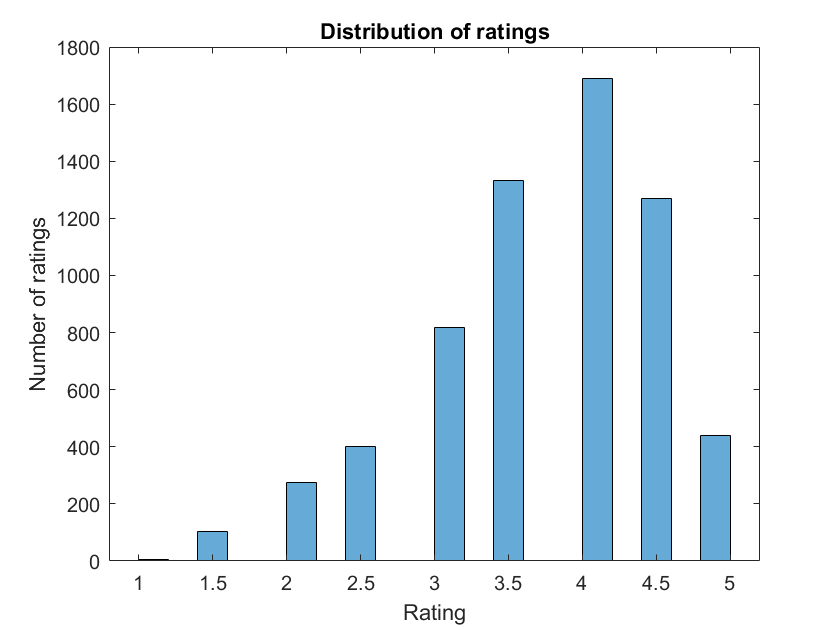

fprintf("Standard Deviation of Rating: %f", std(restaurantData.stars))
histogram(restaurantData.stars)
title('Distribution of ratings')
xlabel('Rating')

ylabel('Number of ratings')

trainedModel = struct with fields:
           predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    RequiredVariables: {1×225 cell}
       RegressionTree: [1×1 RegressionTree]
                About: 'This struct is a trained model exported from Regression Learner R2021a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


The figure above shows that there is a skewed unimodal distribution for ratings. As long as ratings have an estimated rating of 4+ based on their location and category, they have a good location.

## Machine Learning

We performed a 5-fold validation with the Coarse Tree algorithm. This model had the best results for our data. Below are our results:

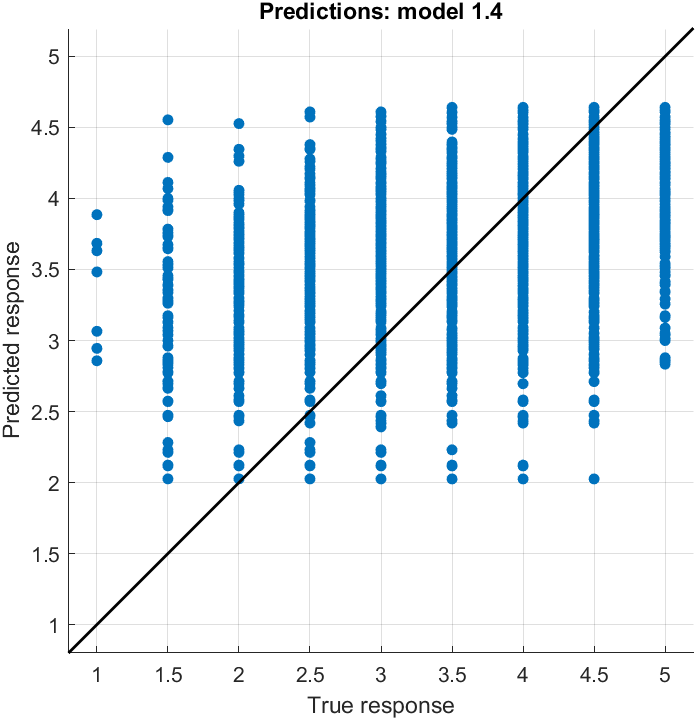

Our model had a RMSE of 0.70305 for the validation data. This shows that our model could approximately predict the rating within one "bucket" (0.5 stars). As can be seen, the model did predict higher scores for the very highly rated restaurants, indicating a slight association between location, cuisine, and rating for the best restaurants. However, there was a smaller overall assocation than was expected.

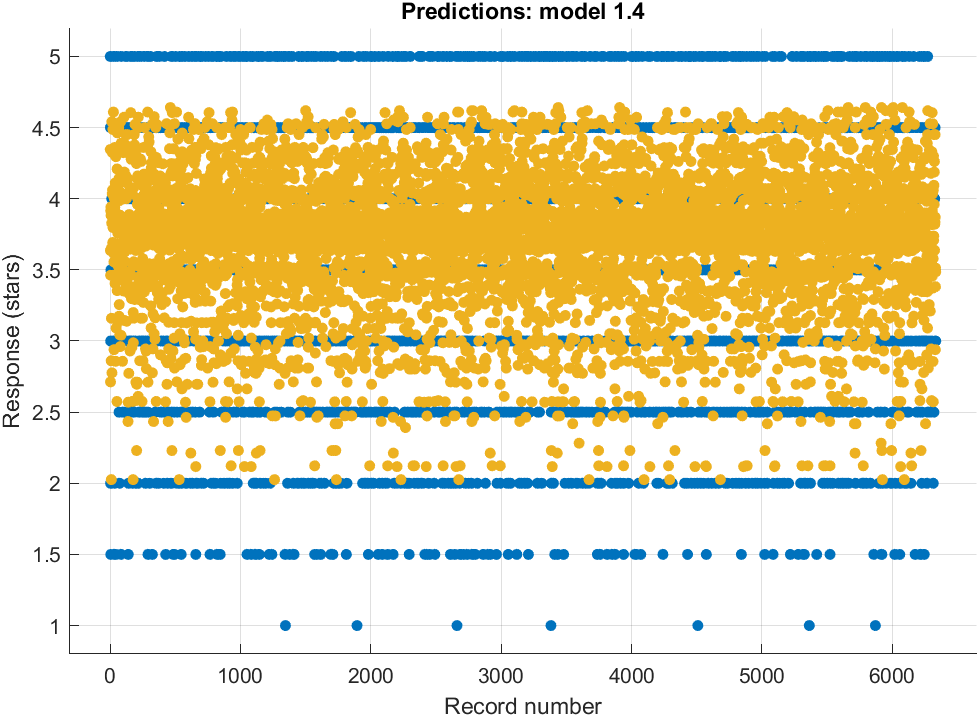

This figure shows the predicted ratings (yellow) vs the actual ratings (blue). Many restaurants' ratings were accurately predicted based on location and type of cuisine.However, the best and worst restaurants tended to not be predicted correctly, indicating that our model tended toward rating restaurants as average. This is likely due to bias because most restaurants in the dataset were rated around 3-5 to 4 stars.

trainedModel